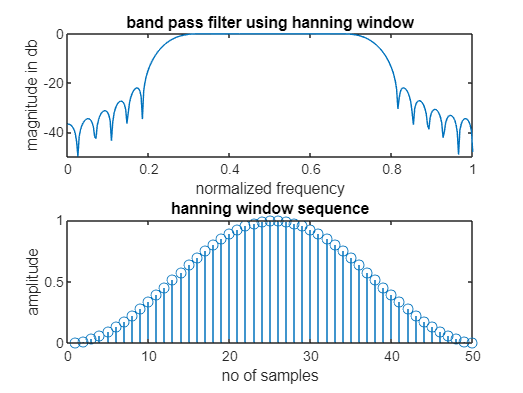

clc;
clear all;
close all;
wcl= 0.25*pi;
wc2 = 0.75*pi;
N=50;
%N = input('enter the value of N');
alpha = (N-1)/2;
n=0:1:N-1;
hd=(sin(wcl*(n-alpha+eps))-sin(wc2*(n-alpha+eps)))./(pi*(n-alpha+eps));
wr=hanning(N);
hn=hd.*wr';
w=0:0.01:pi;
h=freqz(hn,1,w);
subplot(2,1,1);
plot(w/pi,10*log10(abs(h)));
title('band pass filter using hanning window');
xlabel('normalized frequency');
ylabel('magnitude in db');
subplot(2,1,2);
stem(wr);
title('hanning window sequence');
xlabel('no of samples');
ylabel('amplitude');